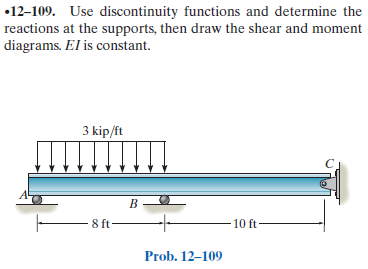

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-109P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-109P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 8*u.ft);
b = b.add('reaction', 'force', 'Rc', 18*u.ft);
b = b.add('distributed', 'force', -3*u.kip/u.ft, [0 8]*u.ft);
b.L = 18*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{x\,\left(x-8\,\mathrm{ft}\right)\,\left(-9\,x^{2}+56\,x\,\mathrm{ft}+448\,{\mathrm{ft}}^{2}\right)}{72\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{8\,\left(x-8\,\mathrm{ft}\right)\,\left(x-18\,\mathrm{ft}\right)\,\left(x-28\,\mathrm{ft}\right)}{45\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{9\,x^{3}-96\,x^{2}\,\mathrm{ft}+896\,{\mathrm{ft}}^{3}}{18\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{8\,\left(3\,x^{2}-108\,x\,\mathrm{ft}+872\,{\mathrm{ft}}^{2}\right)}{45\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(9\,x-64\,\mathrm{ft}\right)}{6}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{16\,\left(x-18\,\mathrm{ft}\right)}{15}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{9\,x-32\,\mathrm{ft}}{3}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ \frac{16}{15}\,\mathrm{kip} & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -3\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 8\,\mathrm{ft}\\ 0 & \text{ if }8\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra, 4) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 10.67\,\mathrm{kip}\\ \mathrm{Rb} & 14.4\,\mathrm{kip}\\ \mathrm{Rc} & -1.067\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

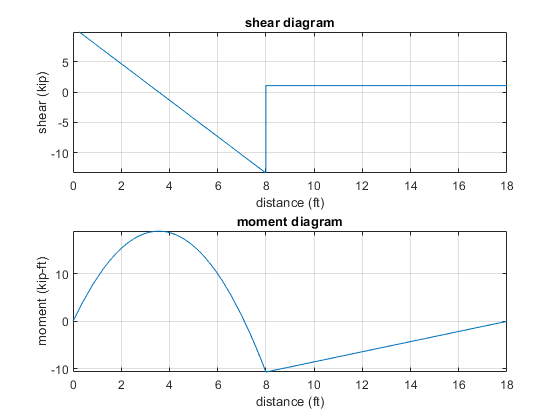

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear ra_vpa;
clear old_assum;